# MCIR: Linear, lumped, time-invariant circuit modeling toolbox for MATLAB

Kerry S. Martin, martin@wild-wood.net

March 14, 2021

## Introduction

MCIR is a toolbox for MATLAB that allows an engineer to analyze linear, lumped, time-invariant circuits using the powerful tools available in MATLAB. Simple commands are used to enter circuits directly into MATLAB via the command line or a script. For example, consider the first-order RC filter circuit shown below.

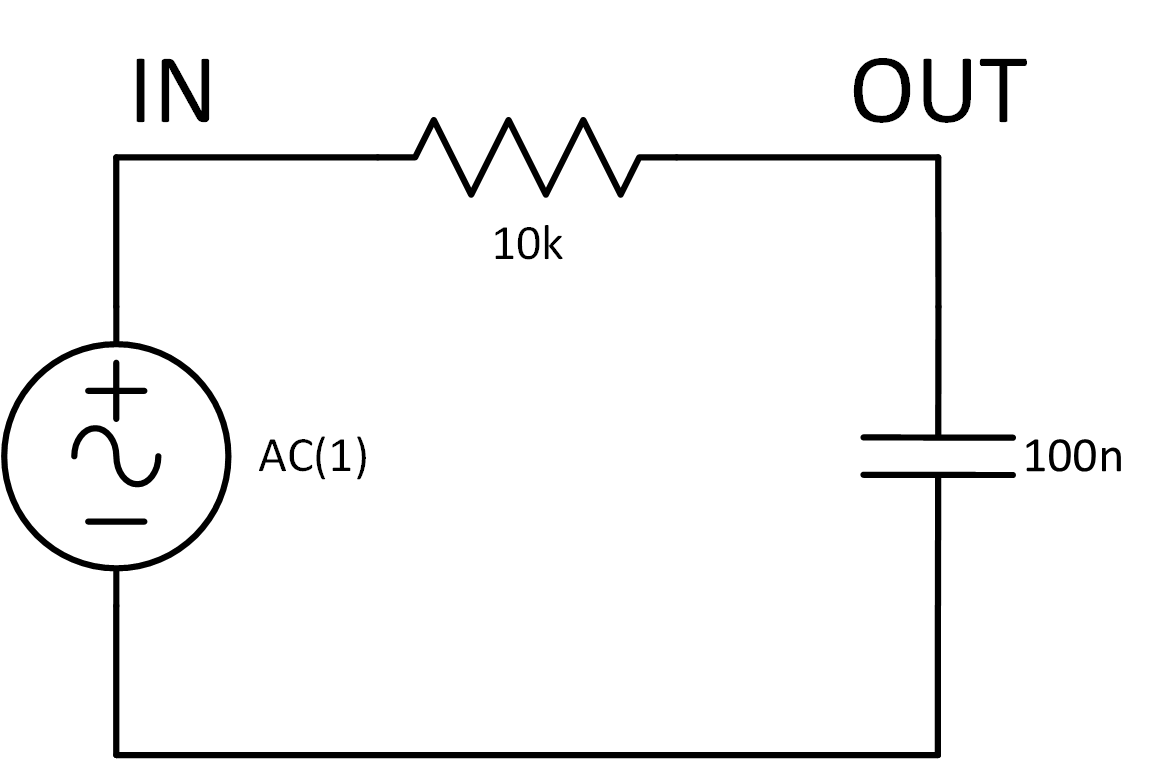

Start by importing the MCIR library:

import MCIR.*

This circuit could be modeled using the following sequence of MCIR commands:

EX1 = Circuit("Example 1");
EX1 <= "Vin in 0 AC(1)"
EX1 <= "R1 in out 10k"
EX1 <= "C1 out 0 100n"

The frequency response could then be plotted using the command:

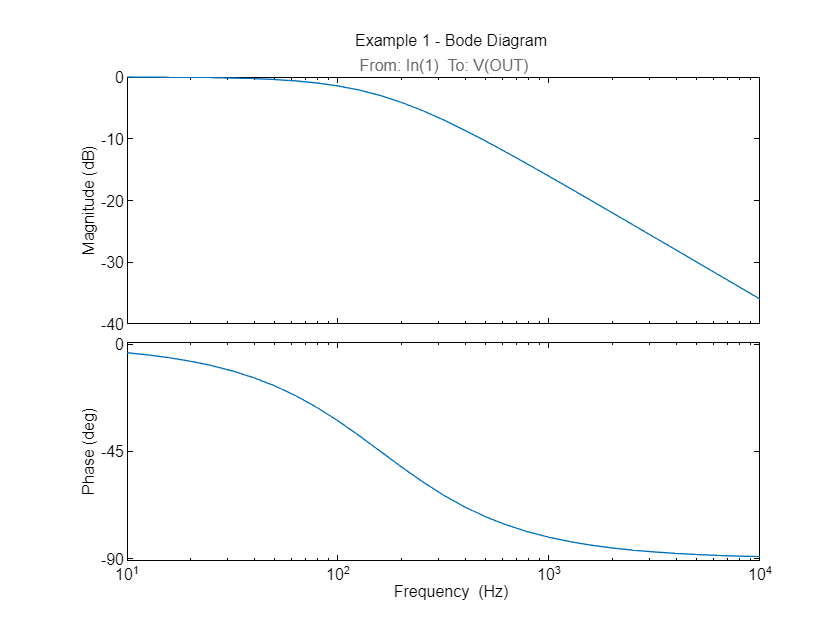

EX1.ac('dec',10,10000,10)

The MCIR library allows DC operating point, transient response, AC frequency response, and AC multi-port analyses to be performed on circuits. Alternately, a state-space model may be generated to allow custom analysis using MATLAB or Simulink.

There are only a few limitations with the MCIR library:

- The circuit must have a reference: node 0 aka V(0)

- It only works for linear components: no transistors, diodes, or other nonlinear components

- It only works for lumped components: no transmission lines

- All nodes must have a finite resistance path back to reference: no open current sources or inductors

This paper will discuss the theory and implementation behind the MCIR library, as well as the usage of the MCIR library for performing fundamental analyses.

## Theory

A linear, lumped, time-invariant system may be described by three sets of equations:

- Dynamic equations: differential equations describing inductors and capacitors

- Static equations: node voltage KCL equations, independent sources, and other static equations

- Output equations: quantities of interest in the system

The three sets of equations may be expressed in matrix form where $x$ is the $N_x \times 1$state vector, $v$ is the $N_v \times 1$static variable vector, $u$ is the $N_u \times 1$ stimulus vector, and $y$ is the $N_y \times 1$ output vector.

The set of $N_x$ dynamic equations takes the matrix form:


$$\begin{array}{rcl}
0 &=& P_{11} \dot{x}+P_{12} v+P_{13\;} u
\end{array}$$


The set of $N_v$ static equations takes the matrix form:


$$\begin{array}{rcl}
0&=&P_{21} x+P_{22} v+P_{23} u
\end{array}$$


The set of $N_y$ output equations takes the matrix form:


$$\begin{array}{rcl}
y&=&P_{31} x+P_{32} v+P_{33} u
\end{array}$$


Combined, these form the system equations:


$$\begin{array}{rcl}
0 &=& P_{11} \dot{x}+P_{12} v+P_{13\;} u\\
0&=&P_{21} x+P_{22} v+P_{23} u\\
y&=&P_{31} x+P_{32} v+P_{33} u
\end{array}$$


Through manipulation, these equations may be arranged into a state-space system of the form:


$$\begin{array}{rcl}
\dot{x} &=& A x \;+\;B u\\
y&=&C x \;+\;D u
\end{array}$$


State-space equations are widely used in the field of control systems to represent linear systems. These equations are easily analyzed to find the steady-state solution, transient response, and frequency response of the system. Matlab excels in its ability to perform analysis on state-space equations.

## Creating a Circuit

When entering a circuit into MCIR, one starts by creating an empty `Circuit` object, giving it a name:

EX2 = Circuit("Example 2")

EX2 =   Circuit with properties:

    circuit_name: 'Example 2'
      components: 0


Next, one adds components to the circuit. Several notations have been included to allow for personal preference. These include the `add()` method as well as the `<=` operator, `<` operator, and `+` operator.

EX2.add("V1 1 0 DC(10)")
EX2 <=  "R1 1 2 10k"
EX2 <   "R2 2 0 100k"
EX2 +   "C1 2 0 1000p"

Components are entered silently (no output generated). However, the circuit may be listed at any time.

EX2.list

* Example 2
V1 1 0 DC=10
R1 1 2 10k
R2 2 0 100k
C1 2 0 1n


Component values may be changed, or components may be entirely replaced using the `alter()` method, or alternately the `>` operator. Note that the full alter provided by the `>` operator can even be used to change the device connections, though that is not done below.

EX2.alter("C1", "10n IC=-5")
EX2 > "R2 2 0 47k"
EX2.list

* Example 2
V1 1 0 DC=10
R1 1 2 10k
R2 2 0 47k
C1 2 0 10n IC=-5


Finally, one or more probes are added to the circuit to indicate which signals are of interest. If no probe is specified, one will be added automatically to probe the last node voltage added to the circuit. Auto-naming (reference prefix followed by @) is demonstrated as probes are added.

EX2 <= "O@ V(2)"
EX2 <= "O@ V(1)"
EX2 <= "O@ V(1,2)"
EX2 <= "O@ I(V1)"
EX2.list

* Example 2
V1 1 0 DC=10
R1 1 2 10k
R2 2 0 47k
C1 2 0 10n IC=-5
O1 V(2)
O2 V(1)
O3 V(1,2)
O4 I(V1)


Now, first find the operating point (DC solution) of the circuit:

EX2.op

Example 2 - Operating Point report:
V(2)	-5
V(1)	10
V(1,2)	15
I(V1)	-1.5m


Components may be remove completely using the `remove()` method, or alternately the `-` operator. Remove three of the probes, leaving only `V(2)`.

EX2.remove("O2")
EX2 - "O3"
EX2 - "O4"
EX2.list

* Example 2
V1 1 0 DC=10
R1 1 2 10k
R2 2 0 47k
C1 2 0 10n IC=-5
O1 V(2)


Finally, run a transient analysis on the circuit using the `tr()` method. The following command simulates the circuit for 1 ms with 1001 linearly spaced points:

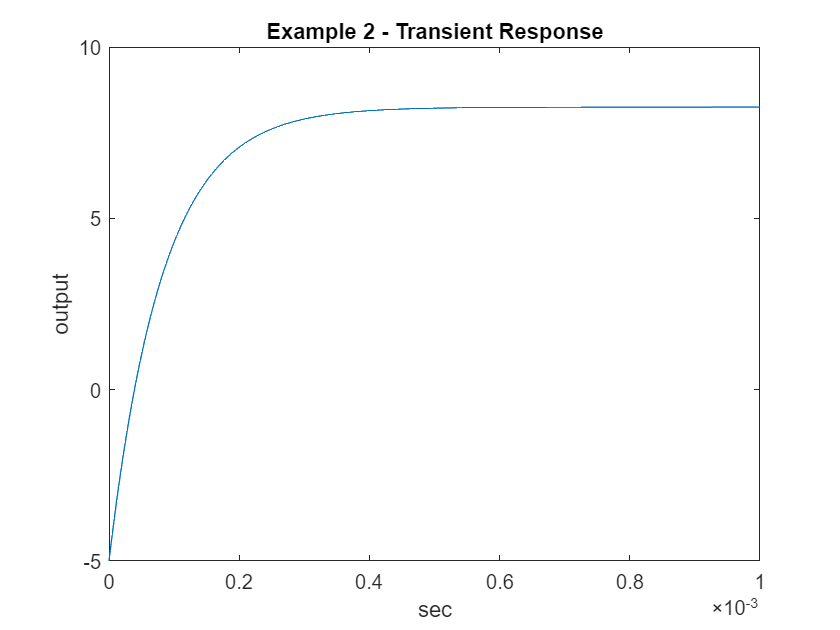

EX2.tr(0.001, 1001)